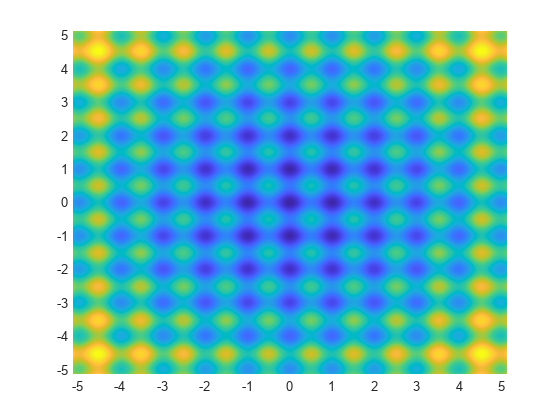

clear; close; clc;
% Parameters
num_particles = 300;
num_dimensions = 2;
max_iterations = 100;
w = 0.5; % Inertia weight
c1 = 1.5; % Cognitive coefficient
c2 = 1.5; % Social coefficient

% Initialize particles
positions = 5-rand(num_particles, num_dimensions)*10;
velocities = rand(num_particles, num_dimensions);
p_best = positions;
g_best = positions(1, :);
g_best_fitness = inf;

% Objective function (example: Sphere function)
%objective_function = @(x) sum(x.^2);

% Plot the objective function


% Create a grid of points
x_limits = [-5.12,5.12];
y_limits = [-5.12,5.12];
xSpace = linspace(x_limits(1), x_limits(2), 400);
ySpace = linspace(y_limits(1), y_limits(2), 400);
[X, Y] = meshgrid(xSpace, ySpace);

% Evaluate the objective function on the grid
Z = arrayfun(@(x,y) objective_function([x;y]), X,Y);

% figure;
% %%Create two axes
% ax1 = axes;
% set(gca,"Color",[0.5,0.5,0.5])
% % plot f
% contourf(X, Y, Z, 50, "-", "EdgeColor","none");


% Main loop
for iter = 1:max_iterations
    for i = 1:num_particles
        % Evaluate fitness
        fitness = objective_function(positions(i, :));
        
        % Update personal best
        if fitness < objective_function(p_best(i, :))
            p_best(i, :) = positions(i, :);
        end
        
        % Update global best
        if fitness < g_best_fitness
            g_best = positions(i, :);
            g_best_fitness = fitness;
        end
    end
    
    for i = 1:num_particles
        % Update velocity
        velocities(i, :) = w * velocities(i, :) + ...
                           c1 * rand * (p_best(i, :) - positions(i, :)) + ...
                           c2 * rand * (g_best - positions(i, :));
        
        % Update position
        positions(i, :) = positions(i, :) + velocities(i, :);
    end

    % Visualization
    clf;
    hold on;
    contourf(X, Y, Z, 50, "-", "EdgeColor","none"); % plot the contours of the function
    scatter(positions(:, 1), positions(:, 2), 'b'); % Particles
    scatter(g_best(1), g_best(2), 'r', 'filled'); % Global best
    title(['Iteration: ', num2str(iter)]);
    xlabel('X');
    ylabel('Y');
    drawnow;
end



disp('Global best position:');
disp(g_best);
disp('Global best fitness:');
disp(g_best_fitness);


function [f] = objective_function(x)
    x = reshape(x, [], 1);
    %f = x(1,:) * (sin(x(1,:)/100*(2*pi)).^2 + 1) .*x(2,:); % cost function
    A = 10;
    f = A*length(x);
    for i = 1:length(x)
        f = f + x(i).^2 - A * cos(2*pi*x(i));
    end
    %c = [x(2,:), x(1,:)]/100; % const function gradient
    %c = 100*[(x(2,:)*(sin((pi*x(1,:))/50)^2 + 1))/100 + (pi*x(1,:)*x(2,:)*cos((pi*x(1,:))/50)*sin((pi*x(1,:))/50))/2500, (x(2,:)*(sin((pi*x(1,:))/50)^2 + 1))/100 + (pi*x(1,:)*x(2,:)*cos((pi*x(1,:))/50)*sin((pi*x(1,:))/50))/2500];
end